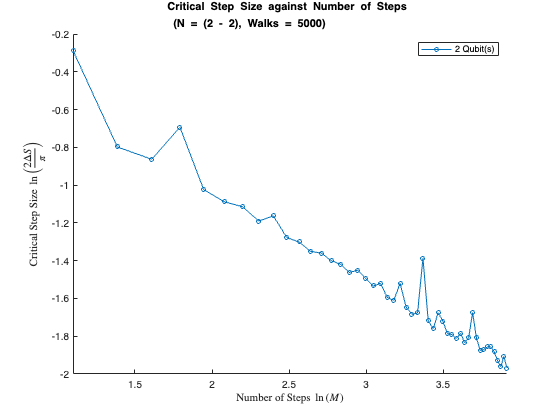

Number_of_Qubits =  2;
Number_of_Walks = 5e4;
Number_of_Steps = 40; 

Step_Size_Resolution = 5e-8;

Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution);


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Number_of_Steps, Step_Size_Resolution)

figure;
hold on;

Data = zeros((Number_of_Qubits-1), Number_of_Steps);

    for N = 2:Number_of_Qubits
    
        Precision = pi*0.5 - acos(1/sqrt(2^N));
    
        for M = 1:Number_of_Steps

        %------- Bisection Root Finding Algorithm -------%

            Lower_Bound = 0;
            Upper_Bound = pi/2;

            Critical_Step_Size = 0;
            
    
            while abs(Lower_Bound-Upper_Bound) > Step_Size_Resolution

               Midpoint = (Lower_Bound+Upper_Bound)/2;
               Lower_Value = Random_Walk_Algorithm(N, M, Number_of_Walks, Lower_Bound) -Precision;
               Midpoint_Value = Random_Walk_Algorithm(N, M, Number_of_Walks, Midpoint) - Precision;
        
                   if abs(Midpoint_Value) <= Step_Size_Resolution
        
                        Critical_Step_Size = Midpoint;
                        break

                   elseif (Lower_Value * Midpoint_Value) < 0

                        Upper_Bound = Midpoint;  
                   else

                        Lower_Bound = Midpoint;  
                   end

            end
            
            if Critical_Step_Size == 0
            Critical_Step_Size = (Lower_Bound + Upper_Bound)/2;
            end

            Data(N-1,M) = Critical_Step_Size;
        
        end      

        plot(log(1:Number_of_Steps), log((2/pi)*Data(N-1,:)), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubit(s)', N));
    end

    xlabel('Number of Steps $ \ln \left( M \right) $', 'Interpreter', 'latex');
    xlim([log(3),log(Number_of_Steps)]);
    ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
    title(sprintf('Critical Step Size against Number of Steps \\newline (N = (2 - %d), Walks = %d)', Number_of_Qubits, Number_of_Walks));
    legend;

hold off;
end

function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)

    Final_Distances = zeros(1,Number_of_Walks);

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
    Vector_Database= randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    
    for i = 1:Number_of_Walks
     
            Vector = Pole_Vector; 
        
                    for j = 1:Number_of_Steps

                        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);

                        Orthogonal_Vector = Selected_Vector - dot(Vector,Selected_Vector)*Vector;

                        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

                        Vector = (cos(Step_Size) * Vector) + (sin(Step_Size) * Normalized_Vector);

                    end 

              Final_Distances(:,i) = Fubini_Study_Distance(Pole_Vector, Vector);
    end 

    RWA = pi*0.5 - mean(Final_Distances);
end 

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end